# **Hilbert Transform and Envelop Extraction**

Analytical Signal in Frequency-Domain approach

## Generate Modulated Signals

close all
clear 

fs = 600; %sampling frequency in Hz
t = 0:1/fs:1-1/fs; %time base

% Amplitude, Information
a_t = 1.0 +0.5* sin(2.0*pi*3.0*t) ; %information signal

% Carrier
%c_t = chirp(t,20,t(end),80); %chirp carrier
c_t = sin(2*pi*50*t); %chirp carrier


% Moduleated Signal
x = a_t .* c_t; %modulated signal


## Tutorial:  Analytical Signal  hilbert()

Form the analytical signal using hilbert()

z = hilbert(x);         


Envelope extraction

%%% Envelope extraction
% inst_amplitude = ___________;     % your code goes here 


%%% inst. phase
inst_phase = unwrap(angle(z));  %inst phase


%%% inst. frequency (carrier)
inst_freq = diff(inst_phase)/(2*pi)*fs; 

%%% Regenerate the carrier from the instantaneous phase
regenerated_carrier = cos(inst_phase);

Plot results

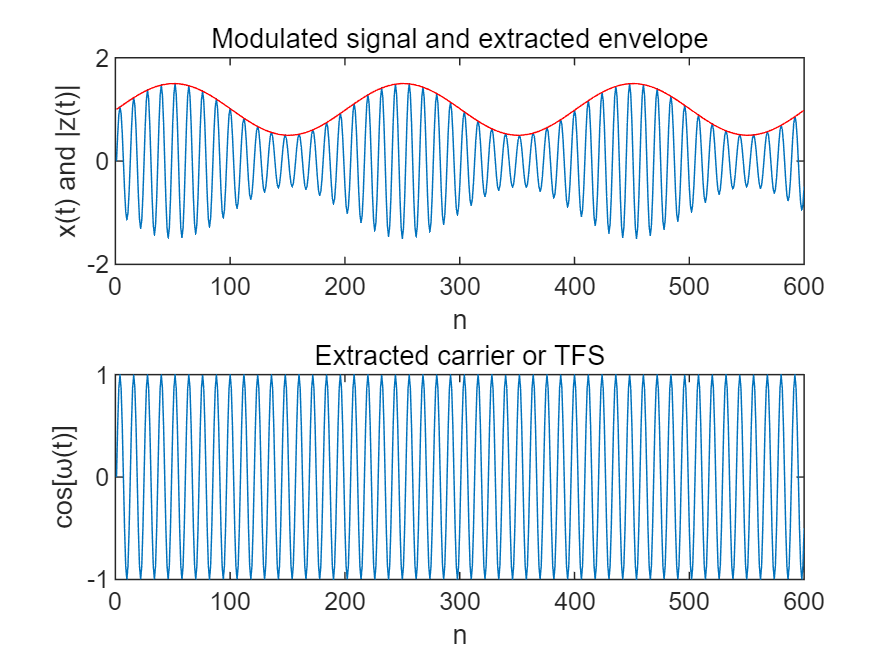

figure(1)
subplot(2,1,1); plot(x);hold on; %plot the modulated signal
plot(inst_amplitude,'r'); %overlay the extracted envelope
title('Modulated signal and extracted envelope'); xlabel('n'); ylabel('x(t) and |z(t)|');
subplot(2,1,2); plot(cos(inst_phase));
title('Extracted carrier or TFS'); xlabel('n'); ylabel('cos[\omega(t)]');

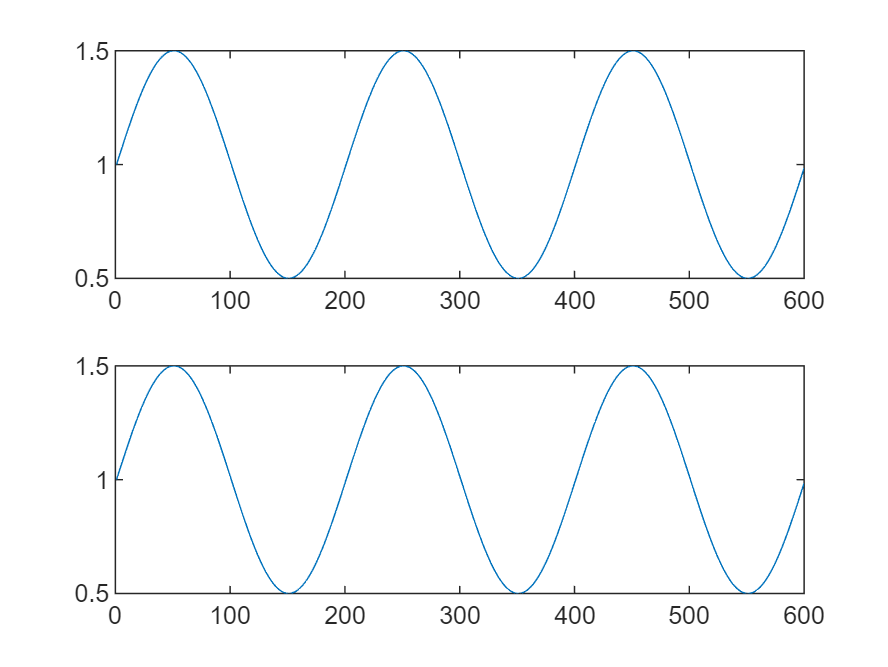


figure(2)
subplot(2,1,1); plot(a_t);
subplot(2,1,2); plot(inst_amplitude);

## Exercise:  

Create a function that returns Analytical Signal z(t)=Zr(t)+j(zi)

z(t) = analyticSignal(x);

where z(t) is ifft of Z[m] of 

### 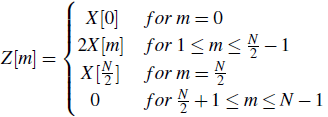

% function z = analyticSignal(x); %construct analytic signal
% x is a real-valued record of length N, where N is even %returns the analytic signal z[n]

x = x(:); %serialize
N = length(x);


%%% YOUR CODE GOES HERE
% FFT of x
% X =___________ ;      %YOUR CODE

% Create P[m]=Z[m]  from m=1 to N
%P=_______________;        %YOUR CODE

% Create z(t)=Zr+j(Zi) from ifft(P)
%z =______________;       %YOUR CODE

% Envelope extraction
% inst_amplitude = _________; 

% end



plot results

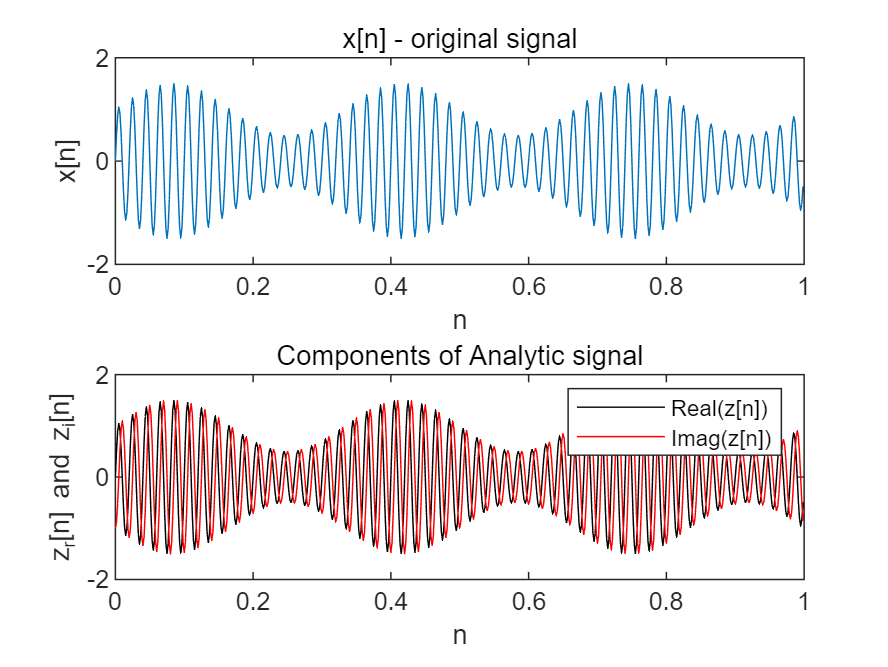

figure(3)
subplot(2,1,1); plot(t,x);
title('x[n] - original signal'); xlabel('n'); ylabel('x[n]');
subplot(2,1,2); plot(t, real(z), 'k'); hold on;
plot(t, imag(z), 'r');
title('Components of Analytic signal'); 
xlabel('n'); ylabel('z_r[n] and z_i[n]');
legend('Real(z[n])','Imag(z[n])');

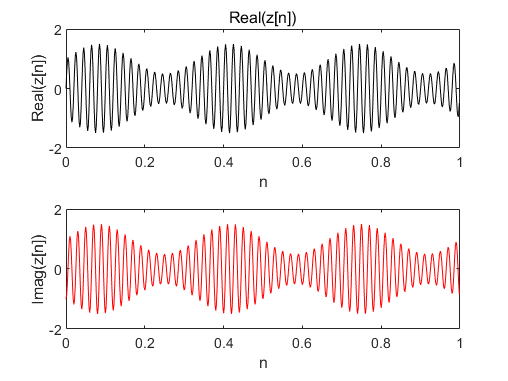


figure(4)
subplot(2,1,1); plot(t, real(z), 'k'); 
title('Real(z[n])'); xlabel('n'); ylabel('Real(z[n])');
subplot(2,1,2); plot(t, imag(z), 'r');
xlabel('n'); ylabel('Imag(z[n])');

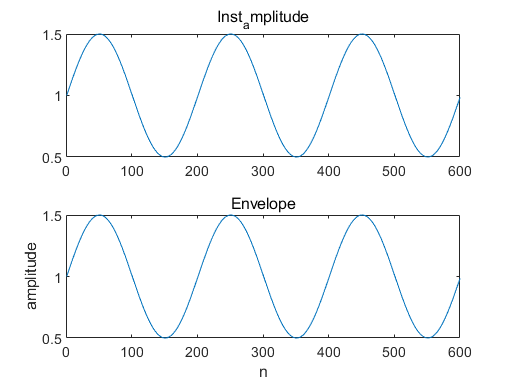


figure(5)
subplot(2,1,1); plot(a_t);
title('Inst_amplitude');
subplot(2,1,2); plot(inst_amplitude);
title('Envelope');
xlabel('n'); ylabel('amplitude');